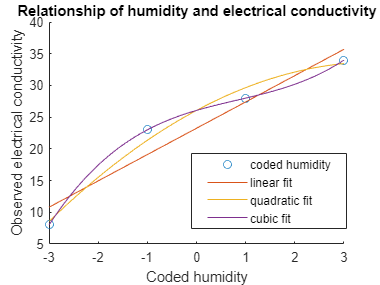

y = [8 23 28 34];
hum_perc = [20 30 40 50];
x_coded = (hum_perc-35)/5;
b = y';
one = ones(4, 1);
lin = linspace(-3, 3, 100);
lin_sqrt = linspace(20, 50, 100);

% a: linear model
Aa = [one x_coded'];

xa = (Aa'*Aa)\Aa'*b;
linear_func = xa(1)+xa(2)*x_coded;

% b: quadratic model
Ab = [one x_coded' (x_coded').^2];
xb = Ab'*Ab\Ab'*b;
quad_func = xb(1)+xb(2)*lin+xb(3)*lin.^2;

% c: 
Ac = [one x_coded' (x_coded').^2 (x_coded').^3];
xc = Ac'*Ac\Ac'*b;
cubic_func = xc(1)+xc(2)*lin+xc(3)*lin.^2+xc(4)*lin.^3;

% bonus: square root
As = [one sqrt(hum_perc')];
xs = As'*As\As'*b;
sqrt_func = xs(1)+xs(2)*sqrt(lin_sqrt);

figure()
scatter(x_coded, y);
hold on
plot(x_coded, linear_func, lin, quad_func, lin, cubic_func);
title("Relationship of humidity and electrical conductivity", FontSize = 11)
xlabel("Coded humidity")
ylabel("Observed electrical conductivity")
legend("coded humidity", "linear fit", "quadratic fit", "cubic fit")

legend("Position",[0.50585,0.20019,0.40506,0.25949])

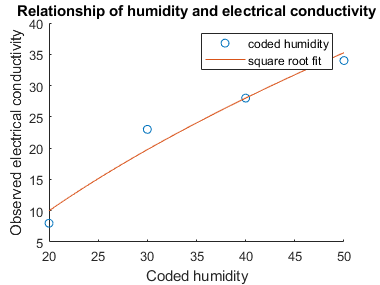


figure
scatter(hum_perc, y);
hold on
plot(lin_sqrt, sqrt_func);
title("Relationship of humidity and electrical conductivity", FontSize = 11)
xlabel("Coded humidity")
ylabel("Observed electrical conductivity")
legend("coded humidity", "square root fit")